clc
clear all

%% define parameters of robot. 
% old method assumed wheel1_x=CoG_x=CoG_y = 0
wheel1_x = 0.131;
wheel1_y = 0.187795;
CoG_x = 0.0147329362484;
CoG_y = 0.00176019942301;
v_max = 2.0;

%% Define formulas
r_CoG     = @(r_c) sqrt( (r_c + CoG_y)^2    + (CoG_x)^2    );
r_1       = @(r_c) sqrt( (r_c + wheel1_y)^2 + (wheel1_x)^2 );
theta_CoG = @(r_c) atan( CoG_x    / (r_c + CoG_y)    );
theta_1   = @(r_c) atan( wheel1_x / (r_c + wheel1_y) );

a_ges = @(r_c) v_max^2 * r_CoG(r_c) / r_1(r_c)^2 * cos(theta_1(r_c))^2 * cos(theta_CoG(r_c));
reverse_a_ges = @(r_c) -a_ges(r_c);

%% Non linear solver
disp("Using non linear solver")

Using non linear solver


tic
best_r_c = fmincon(reverse_a_ges, 10, [],[],[],[], 0, 3)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


best_r_c = 0.2666

a_ges(best_r_c)

ans = 4.4316

toc

Elapsed time is 0.344125 seconds.



%% Brute force method
disp("Using brute force method")

Using brute force method


tic
r_c_values   = 0:0.001:3;
a_ges_values = zeros(size(r_c_values));
idx = 0;
for i=r_c_values
    idx = idx+1;
    a_ges_values(idx) = a_ges(i);
end
[best_a,bestIndex] = max(a_ges_values);
r_c_values(bestIndex)

ans = 0.2670

best_a

best_a = 4.4316

toc

Elapsed time is 0.026290 seconds.


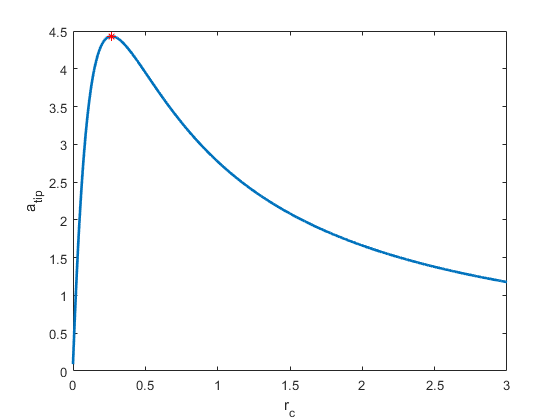


plot(r_c_values, a_ges_values, 'linewidth', 2);
hold on
plot(r_c_values(bestIndex), best_a, 'r*');
xlabel("r_c")
ylabel("a_{tip}")